# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 3;
Deci.Proceed            = true;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru1\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5]; 
Deci.Art.bpf = [1 80];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

Deci.Plot.Math.Form = {'[x4+x2]/2','[x7+x5]/2','[x2+x5]/2','[x4+x7]/2' '[x17-x18]' '[x19-x20]'...
                       '[x2-x4]','[x5-x7]','[x4-x7]','[x2-x5]' '[[x2+x3+x4+x13+x14+x15]/6]' '[[x5+x6+x7+x10+x11+x12]/6]' '[x27-x28]'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[2:7] [17:18] [19:20] [21:22] [23:24] [25] [26] [27:28] [29]};
Deci.Plot.Title = {'All Opt trials' 'Prediction Error' 'Valence Signals' 'Valence-independent Prediction Error' 'PE-independent Valence Signals' ...
                    'Valence-Dependent Prediction Error' 'PE-dependent Valence Signal' 'Expectation Signals' 'Expectation Subtraction'};
Deci.Plot.Subtitle = {{'+R' '+0' '+P' '-R' '-0' '-P'} {'+' '-'} {'R' 'P'} {'+R - +P' '-R - -P'} {'+P - -P' '+R - -R'} {'+ - -'} {'R - P'} {'[BTEOpt+WTEWor]' '[WTEOpt+BTEWor]'} {'[BTEOpt+WTEWor]-[WTEOpt+BTEWor]'}};
Deci.Plot.Figures = [true true true false false false false false false];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [0 .8];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxmin';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = ['All Trials Percent'];
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = ['All Trials RT'];
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

----------------------
Starting Artifactor


searching for artifacts in 62 channels
searching in trial 458 from 458



detected 39 artifacts
the call to "ft_artifact_zvalue" took 88 seconds


searching for artifacts in 4 channels
searching in trial 458 from 458



detected 14 artifacts
the call to "ft_artifact_zvalue" took 13 seconds
detected  39 muscle artifacts
detected  14 eog artifacts
rejected   13 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained    5 trials with artifacts outside critical window
resulting 445 trials
the input is raw data with 62 channels and 458 trials


the call to "ft_redefinetrial" took 10 seconds
the call to "ft_rejectartifact" took 10 seconds
the input is raw data with 62 channels and 445 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 62 channels and 445 trials


showing a summary of the data for all channels and trials


computing metric [----|                                                    ]computing metric [---------/                                               ]computing metric [---------------                                          ]computing metric [-------------------\                                     ]computing metric [------------------------|                                ]computing metric [-----------------------------/                           ]computing metric [------------------------------------                     ]computing metric [----------------------------------------\                ]computing metric [---------------------------------------------|           ]computing metric [--------------------------------------------------/      ]computing metric [---------------------------------------------------------]


417 trials marked as GOOD, 28 trials marked as BAD
62 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 18, 19, 46, 47, 140, 189, 200, 215, 236, 237, 282, 336, 354, 359, 383, 423, 425, 426, 427, 430, 432, 433, 434, 436, 437, 439, 440, 441


the call to "ft_rejectvisual" took 57 seconds
the input is raw data with 62 channels and 417 trials


baseline correcting data 
scaling data with 1 over 41.264226
concatenating data.................................................................................................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 62x2046361
starting decomposition using runica

Input data size [20,2046361] = 20 channels, 2046361 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 5115 frames per ICA weight ((400)^2 = 2046361 weights, Initial learning rate will be 0.001, block size 73.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-0

baseline correcting data 
scaling data with 1 over 46.897737
not concatenating data
starting decomposition using predetermined unmixing matrix
not applying the backprojection matrix to the sensor description
the call to "ft_componentanalysis" took 4 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


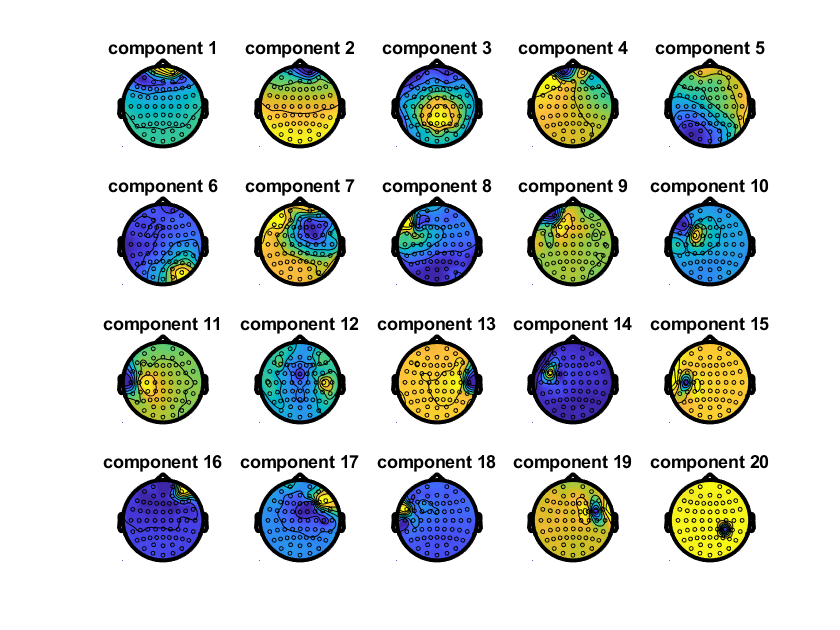

the call to "ft_topoplotIC" took 5 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 62 original channels
the input is raw data with 20 channels and 458 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.

removing 4 components
keeping 16 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 1 seconds


preprocessing


Error using min
Invalid data type. First argument must be numeric or logical.

Error in ft_preproc_bandpassfilter (line 152)
    [B, A] = butter(N, [min(Fbp)/Fn max(Fbp)/Fn]);

Error in preproc (


Deci_Backend(Deci);